Binarize Image

img = im2double(rgb2gray(imread("../Data/MathWorks Images/blueberries.jpg")));

thresh = 128/255;
[Row, Col] = size(img)

Row = 744

Col = 650

binarized = zeros(Row,Col);
for i = 1:1:Row
    for j = 1:1:Col
        if binarized(i,j) < thresh
            binarized(i,j) = 0;
        end
    end
end

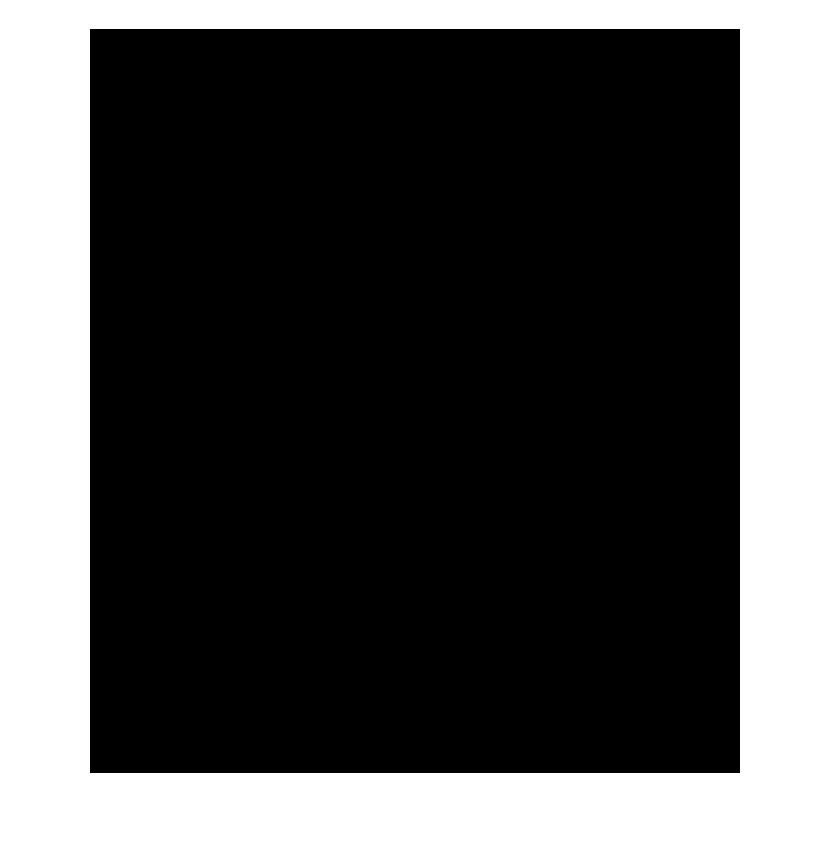

figure; imshow(binarized,[]);

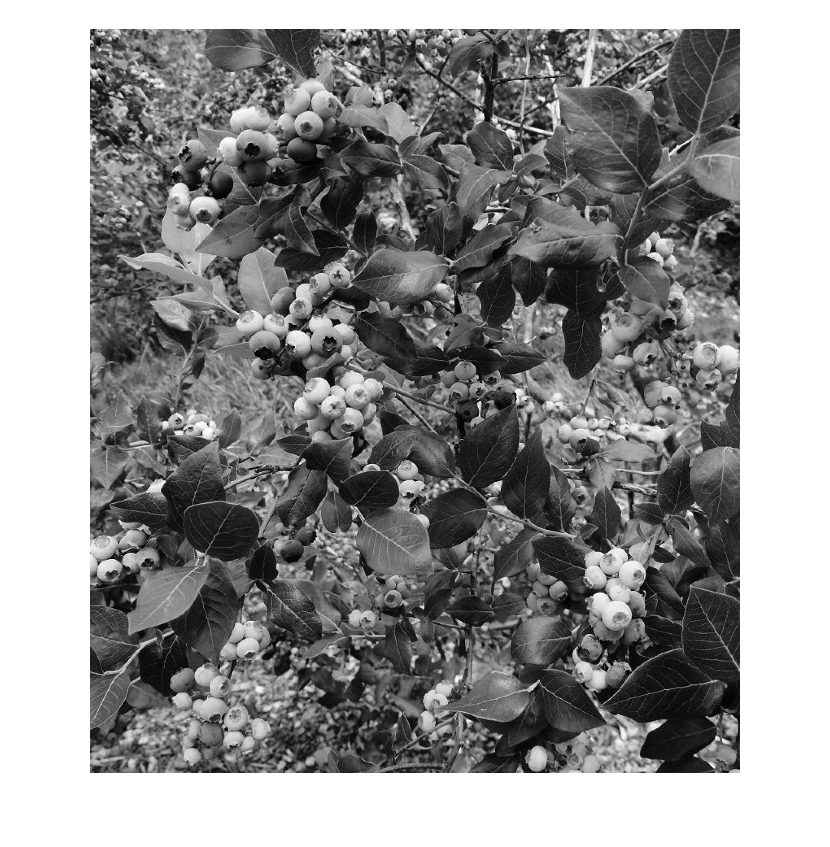

figure; imshow(img,[]);

Without Loops

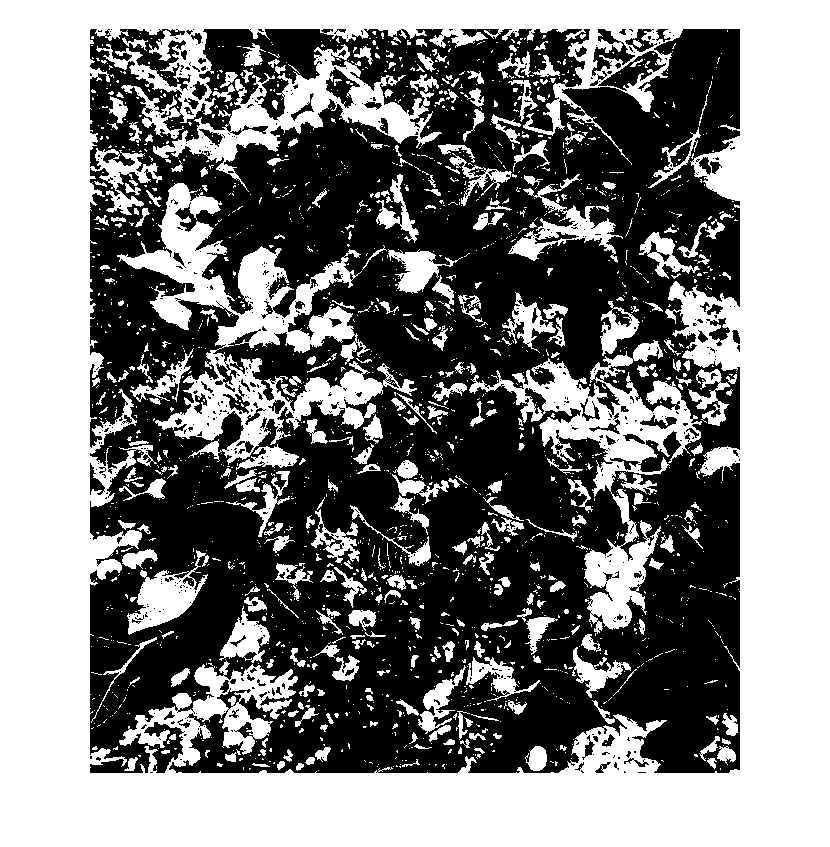

binarized = img;
mask = img > thresh;
binarized(mask) = 255;
figure;
imshow(binarized,[]);

   Convolution Operation

filter = ones(3,3) ./ 9;
[mRow, mCol] = size(filter);
averaged = zeros(Row, Col);
for i = ceil(mRow/2):1:Row-floor(mRow/2)
    for j = ceil(mCol/2):1:Col-floor(mCol/2)
        temp = img(i-floor(mRow/2): i + floor(mRow/2), j - floor(mCol/2) : j + floor(mCol/2));
        averaged(i,j) = sum(temp .* filter, "all");
    end
end

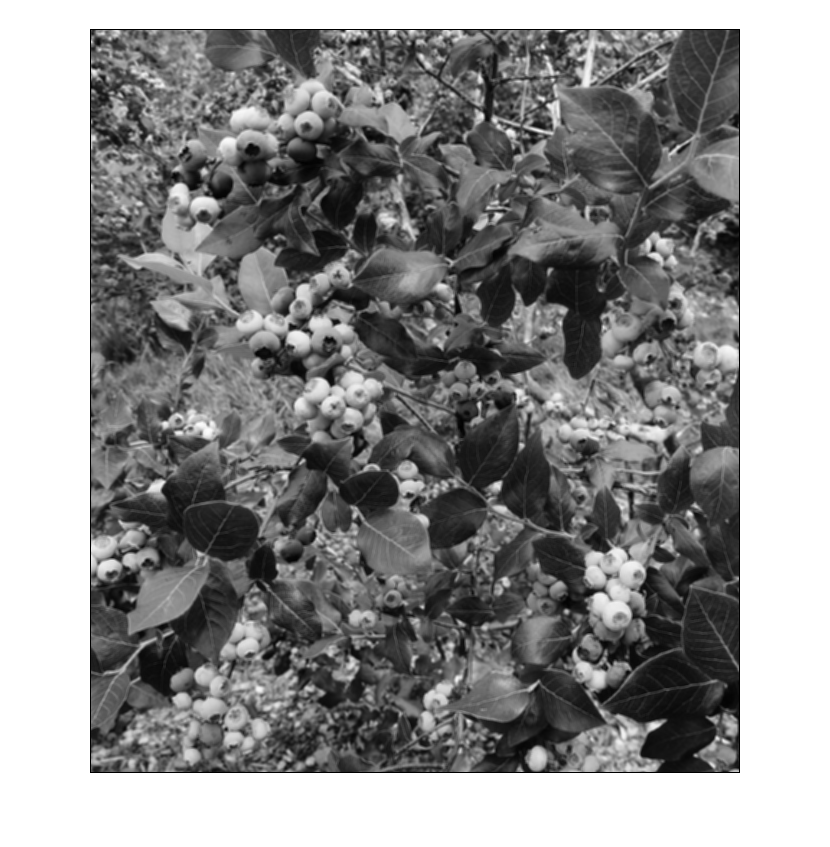

figure;
imshow(averaged)

a = [1 2 3; 4 5 6]

a =      1     2     3
     4     5     6


sum(a,2)

ans =      6
    15
